# CIFI V. Problema: Digitt. Materia: Metodos de Inteligencia Artificial

## Cargamos datos

load Digitt.mat
data

data =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.5972   -0.1960    0.9629    0.4280    0.3834   -0.5393    0.6063   -0.5972    0.6063   -0.6774   -0.3298   -0.5749   -0.1069   -0.8424   -0.7101   -0.8201   -0.3966   -0.3298   -0.1515   -0.5081   -0.8201   -0.1515    1.0074   -0.5883    0.2943    0.1605    0.0714   -0.3743   -0.6864   -0.6864   -0.3743    2.5230   -0.4412   -0.5081    0.5171   -0.5081   -0.0178   -0.5303    0.2943    0.6954   -0.5972   -0.4412    0.2943    0.1516   -0.1069    2.5230    4.3059   -0.1515   -0.1960  

## Income

bins = 0:15000:300000

bins =            0       15000       30000       45000       60000       75000       90000      105000      120000      135000      150000      165000      180000      195000      210000      225000      240000      255000      270000      285000      300000


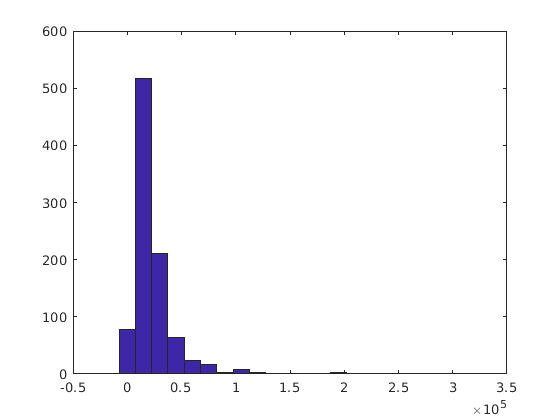

hist(income,bins)

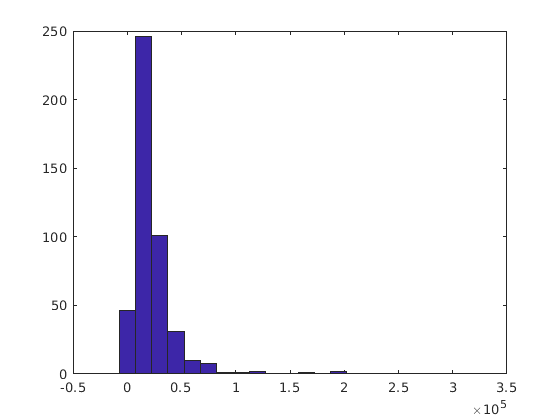

hist(income(Y==1),bins)

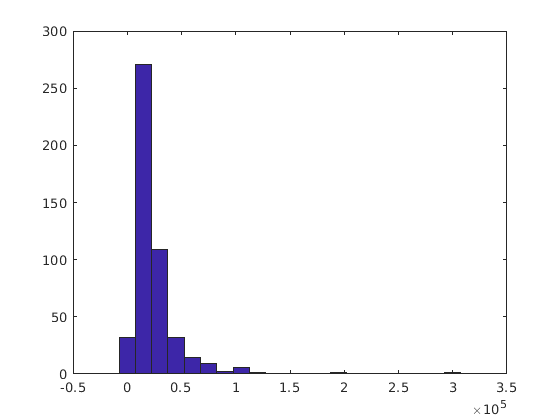

hist(income(Y==0),bins)

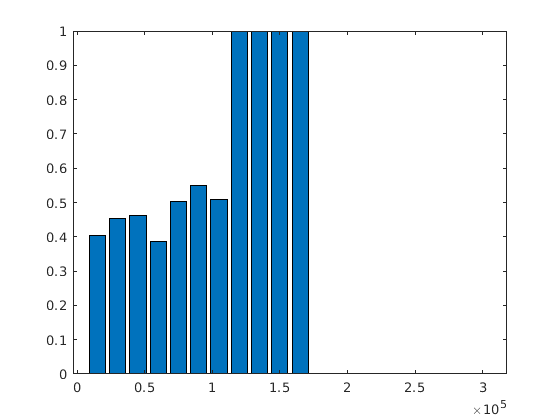

indx_income = bins;
pct_income = zeros(size(indx_income,2)-1,1);
for i=1:size(indx_incom,2)-1
    tmp = income(income>indx_income(i));
    Y_ = Y(income>indx_income(i));
    tmp = tmp(tmp<indx_income(i+1));
    Y_ = Y_(tmp<indx_income(i+1));
    if sum(size(tmp))>0
        pct_income(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_income(2:end),pct_income)

## Age

bins = 18:5:68

bins =     18    23    28    33    38    43    48    53    58    63    68


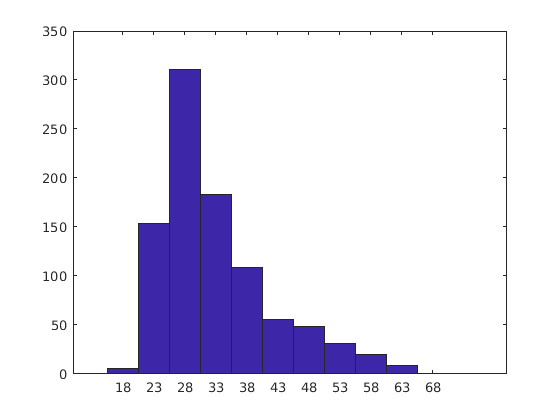

hist(age, bins)

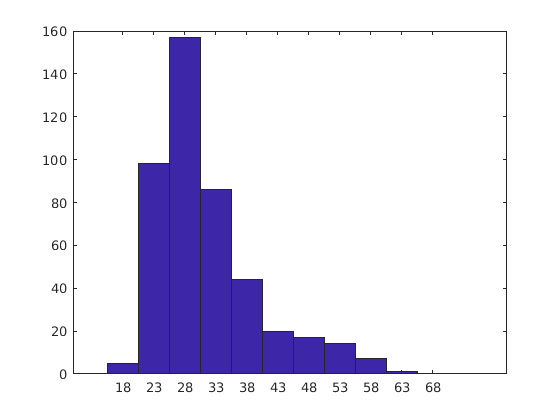

hist(age(Y==1), bins)

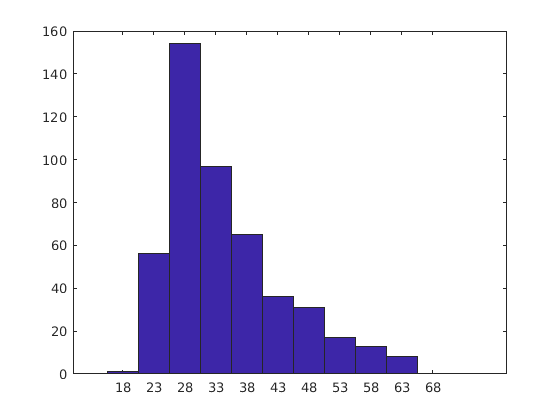

hist(age(Y==0), bins)

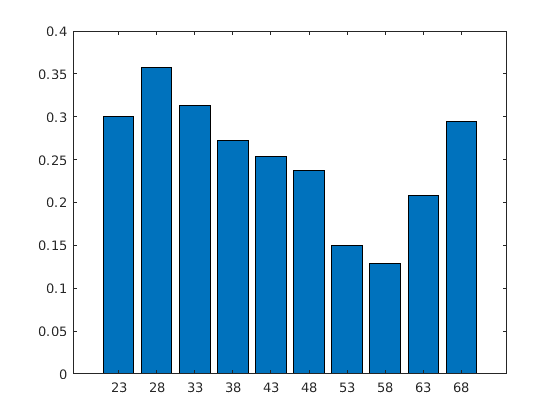

indx_age = bins;
pct_age = zeros(size(indx_age,2)-1,1);
for i=1:size(indx_age,2)-1
    tmp = age(age>indx_age(i));
    Y_ = Y(age>indx_age(i));
    tmp = tmp(tmp<indx_age(i+1));
    Y_ = Y_(tmp<indx_age(i+1));
    if sum(size(tmp))>0
        pct_age(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_age(2:end),pct_age)

## Score

bins = 622:7:727

bins =    622   629   636   643   650   657   664   671   678   685   692   699   706   713   720   727


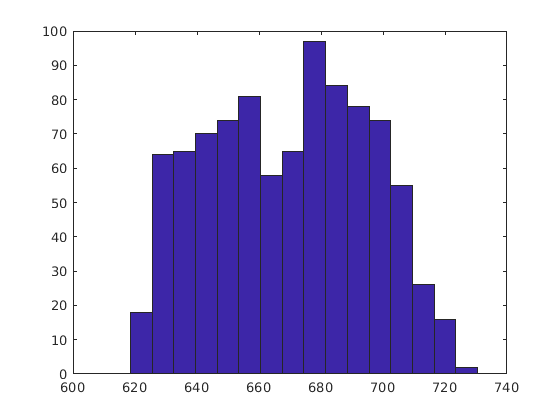

hist(score, bins)

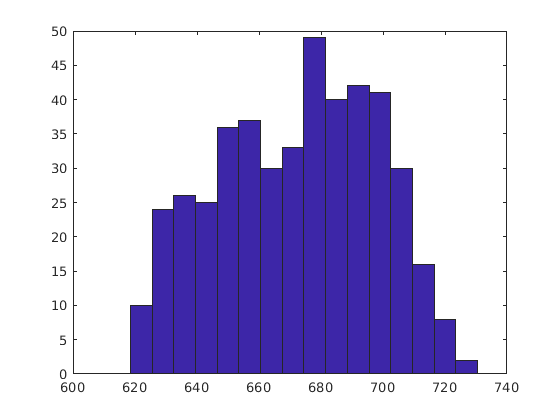

hist(score(Y==1), bins)

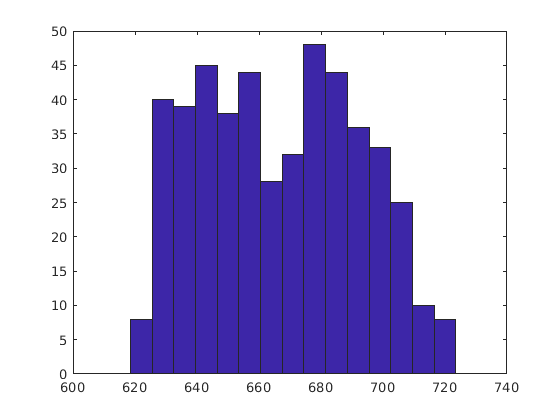

hist(score(Y==0), bins)

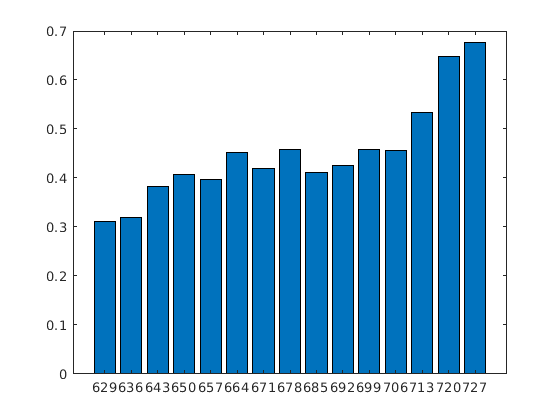

indx_score = bins;
pct_score = zeros(size(indx_score,2)-1,1);
for i=1:size(indx_score,2)-1
    tmp = score(score>indx_score(i));
    Y_ = Y(score>indx_score(i));
    tmp = tmp(tmp<indx_score(i+1));
    Y_ = Y_(tmp<indx_score(i+1));
    if sum(size(tmp))>0
        pct_score(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_score(2:end),pct_score)

## Total Debt

bins = 0:20000:500000

bins =            0       20000       40000       60000       80000      100000      120000      140000      160000      180000      200000      220000      240000      260000      280000      300000      320000      340000      360000      380000      400000      420000      440000      460000      480000      500000


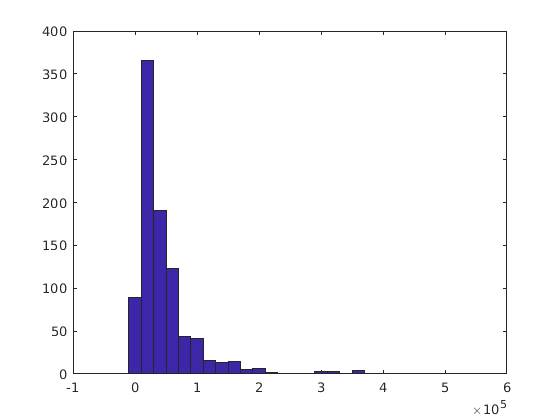

hist(total_debt, bins)

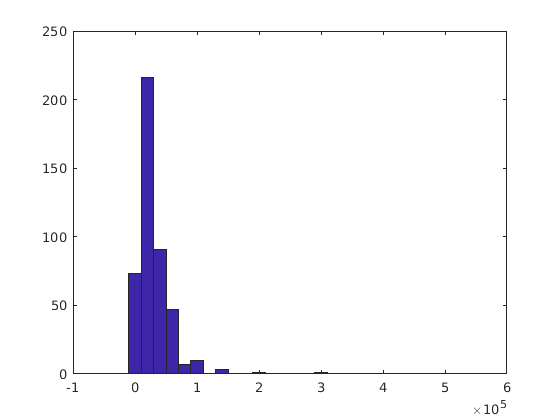

hist(total_debt(Y==1), bins)

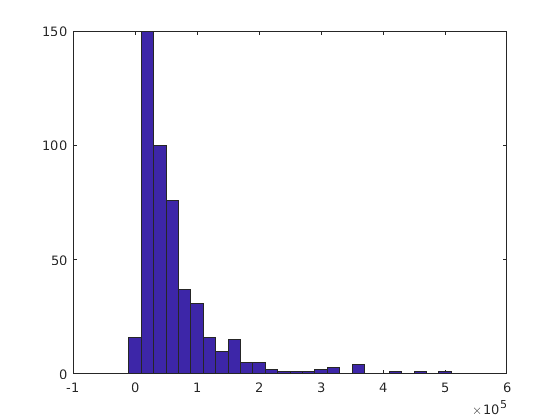

hist(total_debt(Y==0), bins)

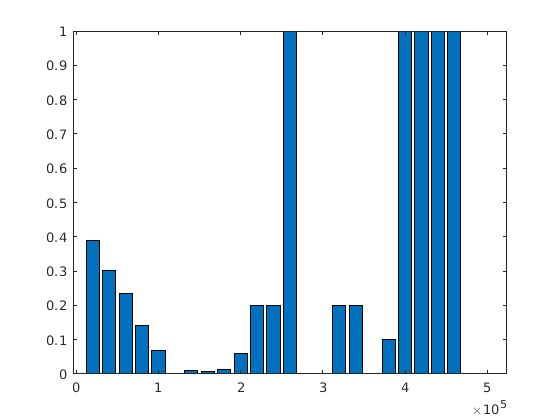

indx_total_debt = bins;
pct_total_debt = zeros(size(indx_total_debt,2)-1,1);
for i=1:size(indx_total_debt,2)-1
    tmp = total_debt(total_debt>indx_total_debt(i));
    Y_ = Y(total_debt>indx_total_debt(i));
    tmp = tmp(tmp<indx_total_debt(i+1));
    Y_ = Y_(tmp<indx_total_debt(i+1));
    if sum(size(tmp))>0
        pct_total_debt(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_total_debt(2:end),pct_total_debt)

## Amount to be lend

bins = 0:20000:500000

bins =            0       20000       40000       60000       80000      100000      120000      140000      160000      180000      200000      220000      240000      260000      280000      300000      320000      340000      360000      380000      400000      420000      440000      460000      480000      500000


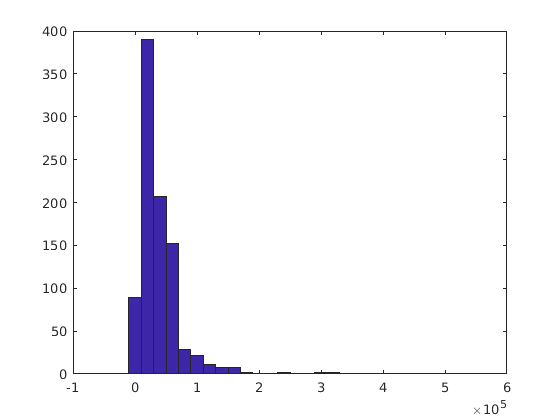

hist(amount_to_be_lend, bins)

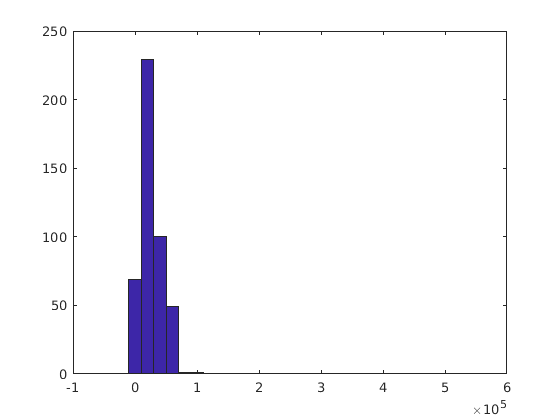

hist(amount_to_be_lend(Y==1), bins)

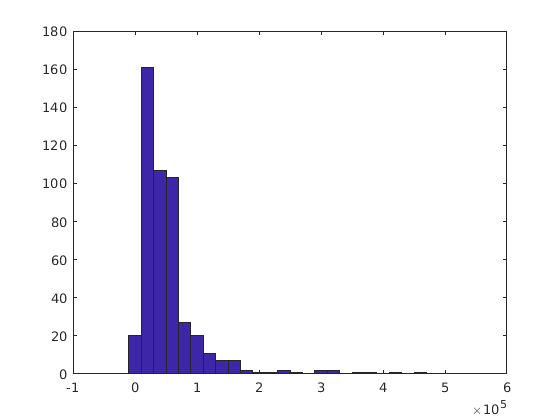

hist(amount_to_be_lend(Y==0), bins)

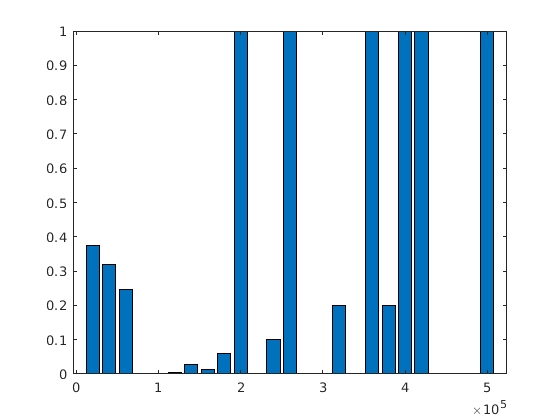

indx_amount_to_be_lend = bins;
pct_amount_to_be_lend = zeros(size(indx_amount_to_be_lend,2)-1,1);
for i=1:size(indx_amount_to_be_lend,2)-1
    tmp = amount_to_be_lend(amount_to_be_lend>indx_amount_to_be_lend(i));
    Y_ = Y(amount_to_be_lend>indx_amount_to_be_lend(i));
    tmp = tmp(tmp<indx_amount_to_be_lend(i+1));
    Y_ = Y_(tmp<indx_amount_to_be_lend(i+1));
    if sum(size(tmp))>0
        pct_amount_to_be_lend(i) = size(tmp(Y_==1))/size(tmp); 
    end
end
bar(indx_amount_to_be_lend(2:end),pct_amount_to_be_lend)

## Variables Categoricas

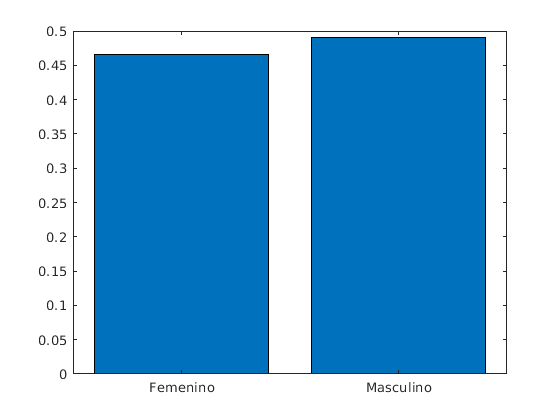

bar(categorical({'Femenino','Masculino'}),sum(gender(Y==1,:),1)./sum(gender(:,:),1))

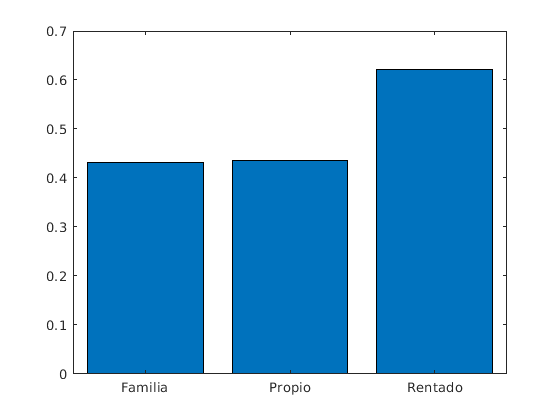

bar(categorical({'Familia','Propio','Rentado'}),sum(housing_type(Y==1,:),1)./sum(housing_type(:,:),1))

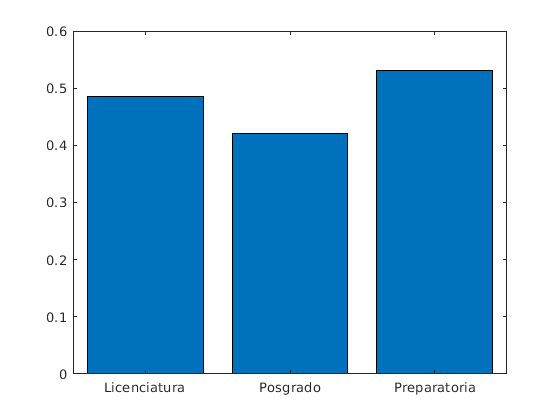

bar(categorical({'Licenciatura','Posgrado','Preparatoria'}),sum(level_of_studies(Y==1,:),1)./sum(level_of_studies(:,:),1))

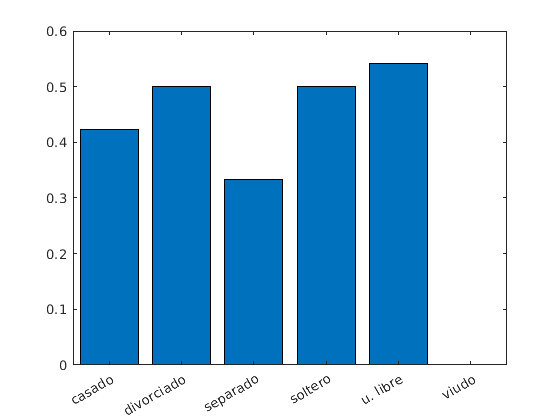

bar(categorical({'casado','divorciado' ,'separado' ,'soltero', 'u. libre','viudo'}),sum(marital_status(Y==1,:),1)./sum(marital_status(:,:),1))

## Los datos y su estructura (datos ya estandarizados)

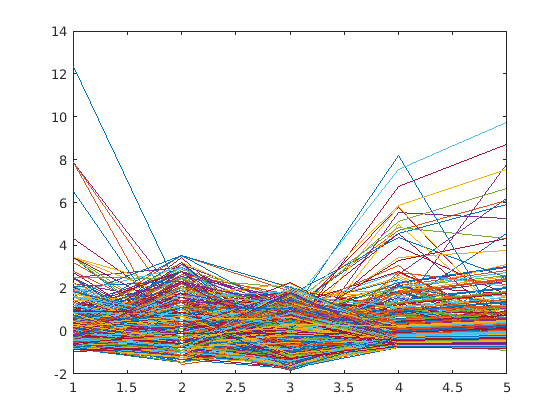

% income age score total_debt amount_to_be_lend
plot(X1')

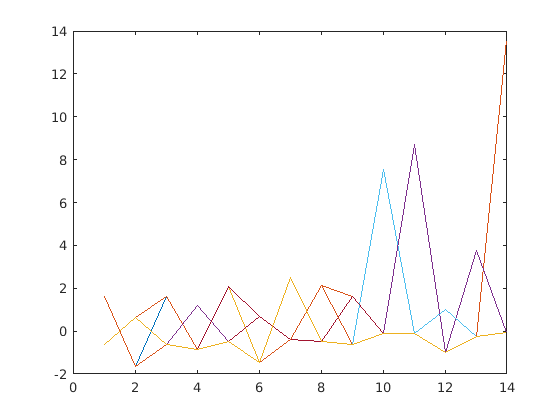

% gender housing_type level_of_studies marital_status
plot(X2')

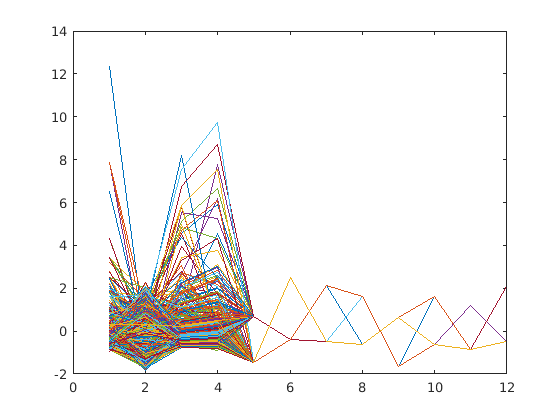

% income score total_debt amount_to_be_lend level_of_studies gender housing_type
plot(X3')

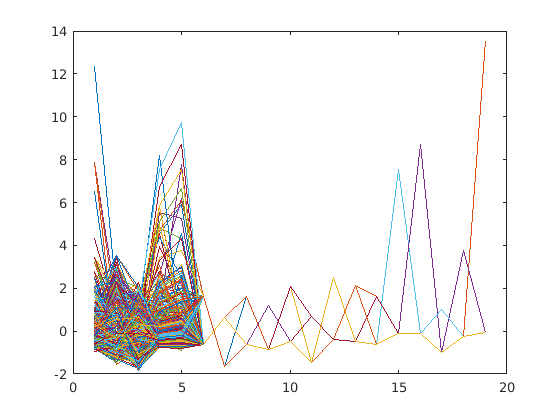

% income age score total_debt amount_to_be_lend gender housing_type level_of_studies marital_status
plot(X4')

## Importancia de los pesos del perceptron

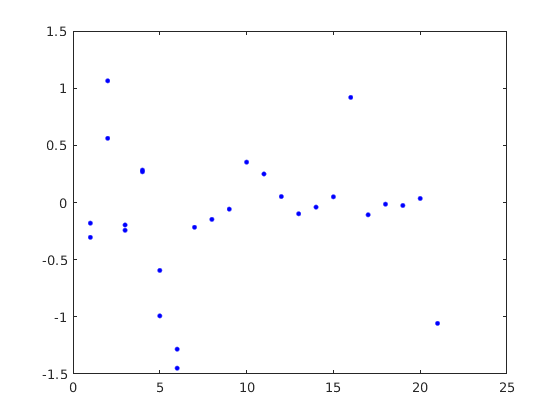

% income age score total_debt amount_to_be_lend
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',1,k));
    hold on 
end
hold off

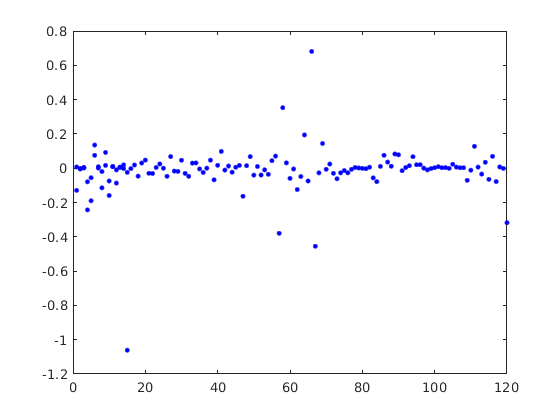


% gender housing_type level_of_studies marital_status
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',2,k));
    hold on 
end
hold off

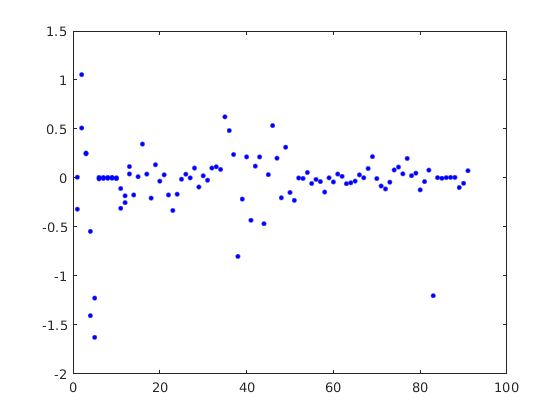


% income score total_debt amount_to_be_lend level_of_studies gender housing_type
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',3,k));
    hold on 
end
hold off

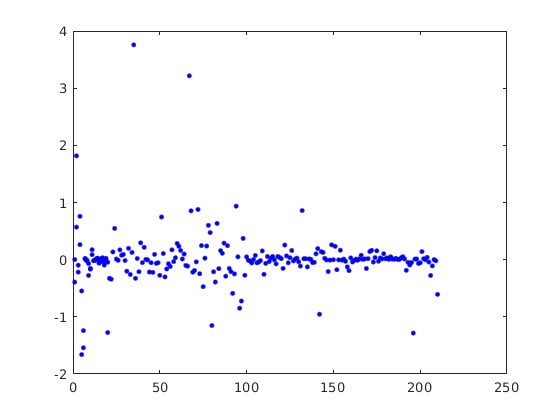


% income age score total_debt amount_to_be_lend gender housing_type level_of_studies marital_status
for k=1:2
    eval(sprintf('plot(Wperceptron.m%dg%d,''b.'',''MarkerSize'',10)',4,k));
    hold on 
end
hold off

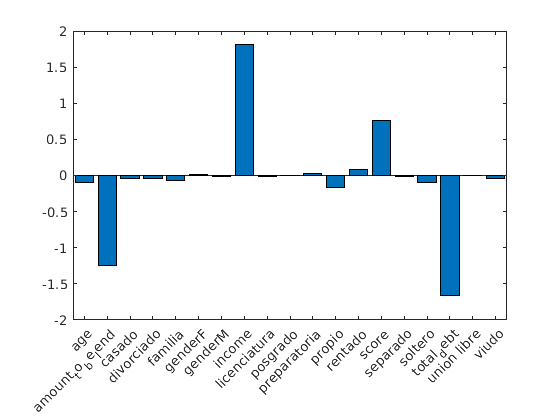

ygraph=Wperceptron.m4g2(2:20);
xgraph=categorical({'income' 'age' 'score' 'total_debt' 'amount_to_be_lend' 'genderF' 'genderM' 'familia' 'propio' 'rentado'  'licenciatura' 'posgrado' 'preparatoria' 'casado' 'divorciado' 'separado' 'soltero' 'union libre' 'viudo'});
bar(xgraph,ygraph)

## Desempeño de los modelos

Desempenio

Desempenio = struct with fields:
    m1g1: [0.6882 0.7394 0.6587]
    m2g1: [0.5771 0.3808 0.6000]
    m3g1: [0.6926 0.7283 0.6673]
    m4g1: [0.6936 0.7372 0.6660]
    m1g2: [0.7033 0.7728 0.6673]
    m2g2: [0.6052 0.5367 0.6040]
    m3g2: [0.7141 0.7528 0.6870]
    m4g2: [0.7627 0.7884 0.7390]


## Estimados (Predicciones)

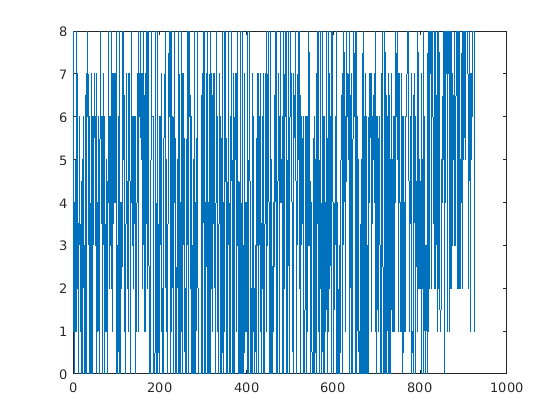

YgGlobal = zeros(size(Y));
for k=1:2
    for i=1:4
        eval(sprintf('YgGlobal = YgGlobal + Yg.m%dg%d;',i,k));
    end
end
plot(YgGlobal)

## Porcentaje de aciertos en 1's y 0's para predicciones comunes entre los modelos

zeros_ = zeros(9,1);
ones_ = zeros(9,1);
YgG = YgGlobal

YgG =      1
     8
     0
     1
     1
     3
     7
     1
     8
     2


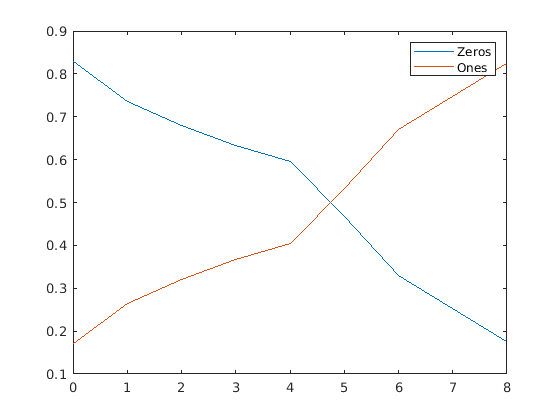

for i=1:9
    tmp00 = sum(~(YgG(YgG==i-1)==i-1)-Y(YgG==i-1));
    tmp01 = sum((YgG(YgG==i-1)==i-1));
    zeros_(i) = 1 + tmp00/tmp01; % 1 - error en los predichos 
    
    tmp10 = sum((YgG(YgG==i-1)==i-1)-Y(YgG==i-1));
    tmp11 = sum(YgG(YgG==i-1)==i-1);
    ones_(i) = 1- tmp10/tmp11; % 1 - error en los predichos 
end
plot(0:8,zeros_)
hold on
plot(0:8,ones_)
hold off
legend('Zeros','Ones')

## Porcentaje de aciertos acumulativos en 1's y 0's para predicciones comunes entre los modelos

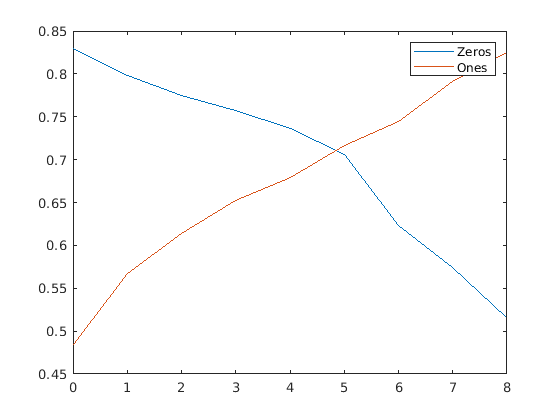

zeros_ = zeros(9,1);
ones_ = zeros(9,1);
for i=1:9
    tmp00 = sum(~(YgG(YgG<i)<i)-Y(YgG<i));
    tmp01 = sum((YgG(YgG<i)<i));
    zeros_(i) = 1 + tmp00/tmp01; % 1 - error en los predichos 
    
    tmp10 = sum((YgG(YgG>=i-1)>=i-1)-Y(YgG>=i-1));
    tmp11 = sum(YgG(YgG>=i-1)>=i-1);
    ones_(i) = 1- tmp10/tmp11; % 1 - error en los predichos 
end
plot(0:8,zeros_)
hold on
plot(0:8,ones_)
hold off
legend('Zeros','Ones')

## Clasificación de usuarios aceptados.

mean([income age score total_debt amount_to_be_lend],1)

ans = 	1.0e+04 *

    2.3398    0.0033    0.0669    4.8371    4.0563


std([income age score total_debt amount_to_be_lend],1)

ans = 	1.0e+04 *

    2.2423    0.0009    0.0026    5.5007    4.3614


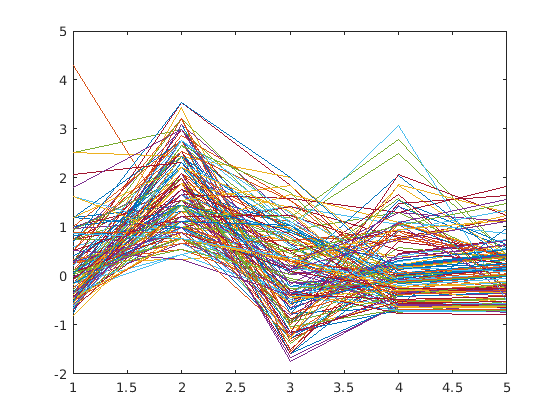

Yg_ = vec2ind(Red.m1.n65(X.m1g1'));
Un = unique(Yg_);
plot(X.m1g1(Yg_==Un(1),2:end)')

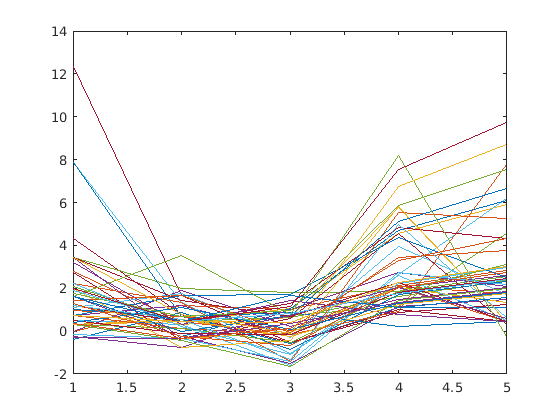

plot(X.m1g1(Yg_==Un(2),2:end)')

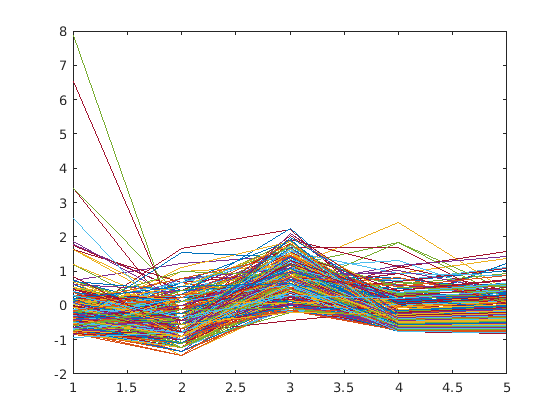

plot(X.m1g1(Yg_==Un(3),2:end)')

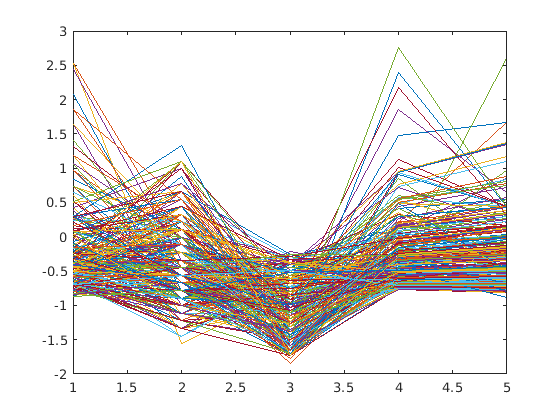

plot(X.m1g1(Yg_==Un(4),2:end)')

% plot(X.m1g1(Yg_==Un(5),2:end)')
% plot(X.m1g1(Yg_==Un(6),2:end)')
% plot(X.m1g1(Yg_==Un(7),2:end)')
% plot(X.m1g1(Yg_==Un(8),2:end)')
% plot(X.m1g1(Yg_==Un(9),2:end)')
% plot(X.m1g1(Yg_==Un(10),2:end)')
% plot(X.m1g1(Yg_==Un(11),2:end)')
% plot(X.m1g1(Yg_==Un(12),2:end)')